## Number of Kills

% option		= "All options";
% 
% sheetName	= "blue_killed_by_red_system";
% dataVar		= "Absolute";
% data		= importData(sheetName, option, fullfile("data", "system_kills_31_03_2021.xlsx"));
% 
% statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems and position
% grpVar		= ["Scenario"; "RedSystem"];
% grpHeatmap(statarray, grpVar, dataVar, option, "AbsoluteKillNumberRedByScenarioByRedSystem", "Absolute kill number red");

% data		= data(contains(data.Assessment, "NO GR"), :);
% statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems and position
% grpVar		= ["Scenario"; "RedSystem"];
% grpHeatmap(statarray, grpVar, dataVar, option, "AbsoluteKillNumberRedByScenarioByRedSystemNoGR", "Absolute kill number red");

## Fraction of Inside/Outside Kills

% statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"; "ShooterLocation"]); % Sum over blue systems
% statarray.Properties.VariableNames{end} = char(dataVar);
% 
% statarrayIn = statarray(statarray.ShooterLocation == "INSIDE", [1:3, 6]);
% statarrayOut = statarray(statarray.ShooterLocation == "OUTSIDE", [1:3, 6]);

% Join tables
% joinedData = innerjoin(statarrayIn,statarrayOut,"Keys",["Assessment",...
%     "Scenario","RedSystem"])
% joinedData.("RatioInOut") = joinedData.Absolute_statarrayIn./(joinedData.Absolute_statarrayIn+joinedData.Absolute_statarrayOut);
% grpVar		= ["Scenario"; "RedSystem"];
% grpHeatmap(joinedData, grpVar, "RatioInOut", option, "RatioInTotalKillRedByScenarioByRedSystem", "Ratio inside/total kills red");

## Number of Engagements

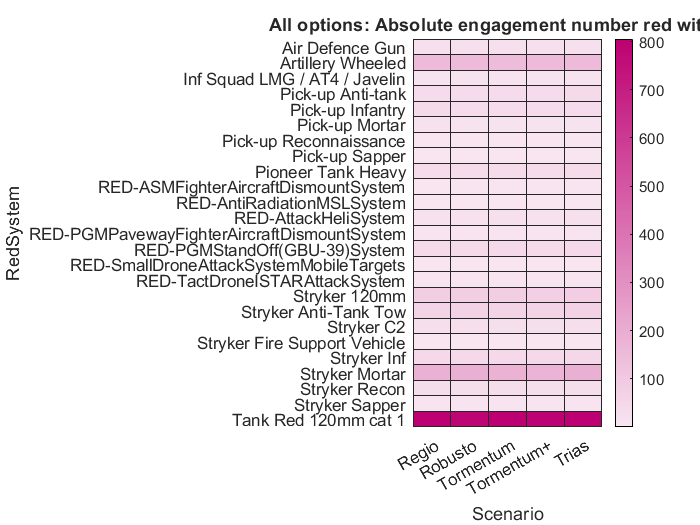

option		= "All options";
sheetName	= "red_shot_costs";
data		= importData(sheetName, option, fullfile("data", "system_kills_02_04_2021.xlsx"));
% data		= importData(sheetName, option, fullfile("data", "system_kills_Indirect Ext GR vs Rgt Heavy BODLUV_05_07_2021.xlsx"));
% data		= importData(sheetName, option, fullfile("data", "system_kills_Indirect Ext NO GR vs Rgt Heavy BODLUV_05_07_2021.xlsx"));
dataVar		= "NumberOfShots";
statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems and position
grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(statarray, grpVar, dataVar, option, "AbsoluteEngagementNumberRedByScenarioByRedSystemWithGR", "Absolute engagement number red with GR");

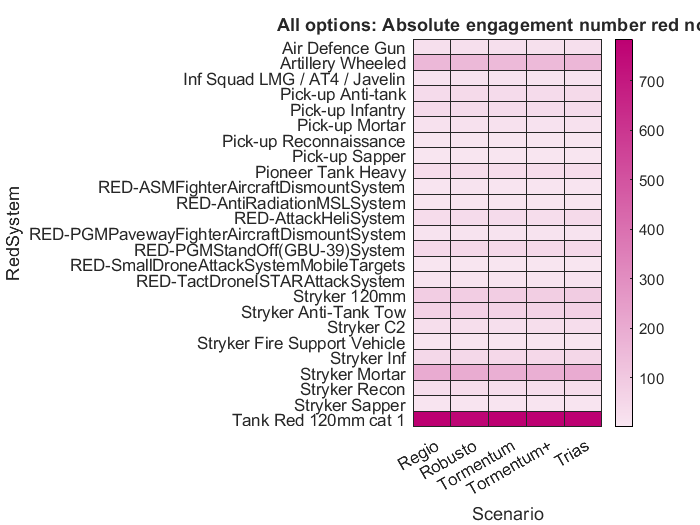


data		= data(contains(data.Assessment, "NO GR"), :);
statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems and position
grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(statarray, grpVar, dataVar, option, "AbsoluteEngagementNumberRedByScenarioByRedSystemNoGR", "Absolute engagement number red no GR");

## Fraction of Inside/Outside Engagements

option		= "All options";
sheetName	= "red_shot_costs";
data		= importData(sheetName, option, fullfile("data", "system_kills_02_04_2021.xlsx"));
dataVar		= "NumberOfShots";

statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"; "ShooterLocation"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems
statarrayIn = statarray(statarray.ShooterLocation == "INSIDE", [1:3, 6]);
statarrayOut = statarray(statarray.ShooterLocation == "OUTSIDE", [1:3, 6]);

% Join tables
joinedData = innerjoin(statarrayIn,statarrayOut,"Keys",["Assessment",...
    "Scenario","RedSystem"]);
joinedData.("RatioInOut") = joinedData.(dataVar+"_statarrayIn")./(joinedData.(dataVar+"_statarrayIn")+joinedData.(dataVar+"_statarrayOut"));
grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(joinedData, grpVar, "RatioInOut", option, "RatioInTotalEngagementsRedByScenarioByRedSystemWithGR", "Ratio inside/total engagements red with GR");


data		= data(contains(data.Assessment, "NO GR"), :);
statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"; "ShooterLocation"], 'OutputVariableNames', char(dataVar)); % Sum over blue systems
statarrayIn = statarray(statarray.ShooterLocation == "INSIDE", [1:3, 6]);
statarrayOut = statarray(statarray.ShooterLocation == "OUTSIDE", [1:3, 6]);

% Join tables
joinedData = innerjoin(statarrayIn,statarrayOut,"Keys",["Assessment",...
    "Scenario","RedSystem"]);
joinedData.("RatioInOut") = joinedData.(dataVar+"_statarrayIn")./(joinedData.(dataVar+"_statarrayIn")+joinedData.(dataVar+"_statarrayOut"));
grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(joinedData, grpVar, "RatioInOut", option, "RatioInTotalEngagementsRedByScenarioByRedSystemNoGR", "Ratio inside/total engagements red no GR");